## Param

wsSrc = mocSegSrc(10);

new moc seg src: tag 10


[para, paraH] = stFld(wsSrc, 'para', 'paraH');
% para.nMi = 10;
% para.nMa = 20;
para.k=8;
TR = 'red'; % reduction(red) no_reduction(nred)
folder = 'k'+string(para.k)+'_('+para.nMi+','+para.nMa+')_'+TR;

## Load Data

% clear variables;
% paths = {'../feat/Cap-B-basal.csv','../feat/Cap-B-treat.csv'};
sel = [1,2,3,4,7,8,9,10];
paths = getAllFile('../feat/20210811/');
paths={paths{sel}};
[X, ends, names] = loadData(paths,para);

tempo reduce 9347 -> 2592
tempo reduce 8247 -> 2106
tempo reduce 10331 -> 2679
tempo reduce 10046 -> 2698
tempo reduce 11097 -> 3025
tempo reduce 9270 -> 2372
tempo reduce 8935 -> 2709
tempo reduce 9337 -> 2347


## Feature

K = conKnl(conDist(X, X), 'nei', .02);
para.nIni = 1;

## ACA

%% init
seg0s = segIni(K, para);

new init seg (p): 1 times


segT = [];
%% aca
[segAca, segAcas] = segAlg('aca', [], K, para, seg0s, segT);

new segmentation (aca): 1 time


% seg = segAca.s;
% label = segAca.G;

## Plot (selected part)

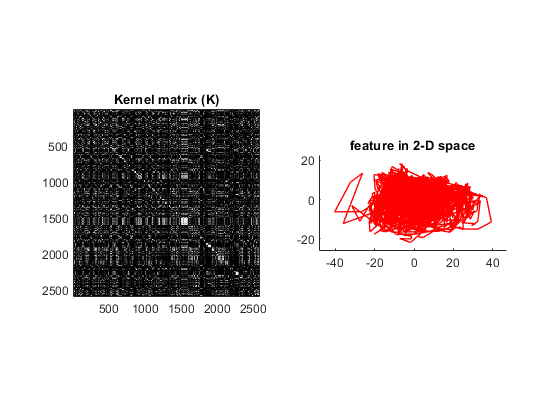

% select part
part = 1;
sK = K(ends(part)+1:ends(part+1),ends(part)+1:ends(part+1));
sX = X(:,ends(part)+1:ends(part+1));
sAP = segAcaPart(segAca,ends,part);

% plot
figure;
showM(sK, 'fig', [1 1 2 1]);
title('Kernel matrix (K)');
showSeq(sX, 'fig', [1 1 2 2]);
title('feature in 2-D space');

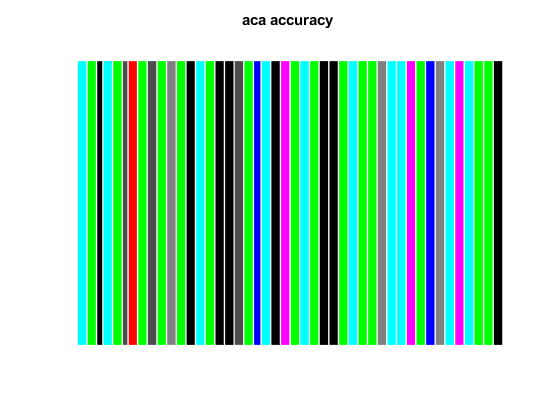

figure;
showSegBar(sAP, 'fig', [1 1 1 1], 'mkSiz', 0, 'lnWid', 1);
title(sprintf('aca accuracy %.2f', segAca.acc));

## Output segments (for each video) + labels sum

parent_folder = './output/'+folder;
if ~exist(parent_folder, 'dir')
    mkdir(parent_folder);
end

[sp,LP] =segPart(segAca.s,segAca.G,ends);
labels = [];

for i=1:size(paths,2)
    seg = sp{i};
    seg = seg - ends(i);
    seg(1)=1;
    seg(end) = ends(i+1)-ends(i)+1;
    label = LP{i};
    labels = [labels sum(label,2)];
    
    name = './output/'+folder+'/seg'+string(i)+'.mat';
    save(name,'seg','label');
end

% output mat
name = './output/'+folder+'/paras.mat';
save(name,'seg','label');

## Cluster analyze plot

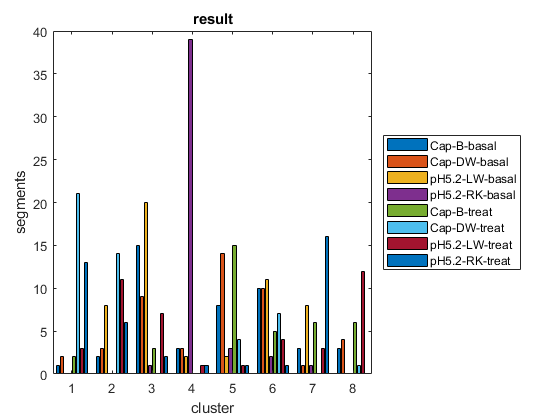

% sel = 1:size(paths,2);
sel = [1,3,5,7,2,4,6,8];

figure;
bar(labels(:,sel));
legend(names(:,sel),'location','eastoutside');
title('result');
xlabel('cluster');
ylabel('segments');

% save figure
name = './output/'+folder+'/resultplot.png';
saveas(gcf,name);

## Functions

function [X, ends, names] = loadData(paths, para)
% ends : end index of each video
    sz = size(paths,2);
    X = [];
    ends = [];
    names = {};
    for i=1:sz
        tmp = table2array(readtable(paths{i}))';
%         ends = [ends size(X,2)];
%         X = [X tmp];
        [~, tmp, ~, ~] = tempoReduce(tmp, para);
        ends = [ends size(X,2)];
        X = [X tmp];
        % get name
        sp = split(paths{i},'/');
        sp = split(sp{end},'.c');
        names{i} = sp{1};
    end
    ends = [ends size(X,2)];
end

function sAP = segAcaPart(segAca,ends,part)
    sAP = segAca;
    [sP, LP] = segPart(segAca.s,segAca.G,ends);
    sAP.s = sP{part};
    sAP.G = LP{part};
end

function [sP, LP] = segPart(seg,label,ends)
% sP:segments partitions
% LP:labels partitions
    sP = {};
    LP = {};
    st = 1;
    st2 = 1;
    for i=1:size(ends,2)-1
        ed = find(seg>=ends(i+1)+1,1);
        sP{i} = seg(:,st:ed);
        LP{i} = label(:,st2:ed-1);
        if seg==ends(i+1)
            st = ed;
            st2 = ed;
        else
            st = ed-1;
            st2 = ed-1;
        end
    end
end

function paths = getAllFile(path)
    paths = {};
    dirs = dir(path);
    folder = {dirs.folder};
    folder = folder{1};
    file = {dirs.name};
    for i=3:size(dirs,1)
        paths{i-2} = strcat(folder,'/',file{i});
    end
end